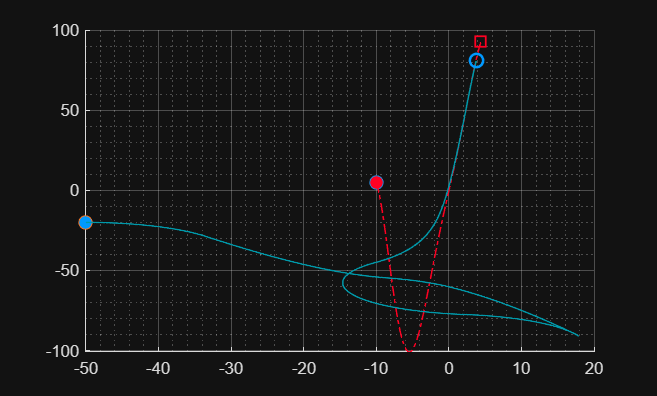

%simulation of Paper
%Nonlinear control design for an unmanned aerial vehicle for path following
%by: Shivam Kumar Singh, Abhinav Sinha, and Shashi Ranjan Kumar
clear;
clc;

syms x;

f = 100*sin(x/5) + x^2*sin(x/2);
% f = x^3/5000;
fm = matlabFunction(f, "Vars",x);
fx = diff(f,1);
fxm = matlabFunction(fx, "Vars",x);

reverse = false;
vRef = 10; %m/s
vr = (reverse)*-vRef + (~reverse)*vRef;
prx = -10;
pr = [prx, fm(prx)];
psir = pi;



simTime = 30;
dt = 0.001;

psim = pi;
pm = [-50,-20];
vmMax = 10;

psiDotMax = 0.5; %rad/s


% gains
M0 = 10;
N0 = 100;

stateM = zeros([simTime/dt + 1, 7]);
stateR = zeros([simTime/dt + 1, 3]);

stateM(1, :) = [pm,0 ,psim, 0, 0, 0 ];
stateR(1, :) = [pr, psir];

figure;
hold on;
grid on; grid minor;
% axis equal;
plot(stateR(1,1), stateR(1, 2), 'o', markersize=8, MarkerFaceColor='#ff0022');
plot(stateM(1,1), stateM(1, 2), 'o', markersize=8, MarkerFaceColor='#0099ff');

i = 2;
for t=dt:dt:simTime
    %%%%%%calculation in previous step for the use in next step
    theta = atan2(stateR(i-1, 2) - stateM(i-1, 2), stateR(i-1, 1) - stateM(i-1, 1));
    stateM(i-1, 6) = wrapToPi(theta - stateM(i-1, 4)); %zeta(t-1)

    %LOS distance error, r(t-1)
    stateM(i-1, 7) = sqrt((stateR(i-1, 1) - stateM(i-1, 1))^2 + (stateR(i-1, 2) - stateM(i-1, 2))^2);

    %psimDot(t-1)
    psimDot = vr*(tan(stateM(i-1, 6))*cos(theta-stateR(i-1, 3)) - sin(theta - stateR(i-1,3)))/stateM(i-1,7) + M0*tan(stateM(i-1, 6)) + N0*stateM(i-1, 6);
    stateM(i-1, 5) = max(min(psimDot, psiDotMax), -psiDotMax);


    %%%%%%calculation for this step
    %vm(t)
    vm = (vr*cos(theta - stateR(i-1, 3)) + M0*stateM(i-1,7))/cos(stateM(i-1, 6));
    stateM(i, 3) = max(min(vm, vmMax), -vmMax);

    %psim(t)
    stateM(i, 4) = wrapToPi(stateM(i-1, 4) + dt*stateM(i-1, 5));


    %xm(t)
    stateM(i, 1) = stateM(i-1, 1) + stateM(i-1, 3)*cos(stateM(i-1, 4))*dt;
    %ym(t)
    stateM(i, 2) = stateM(i-1, 2) + stateM(i-1, 3)*sin(stateM(i-1, 4))*dt;

    %xr(t)
    stateR(i, 1) = stateR(i-1, 1) + vr*cos(stateR(i-1, 3))*dt;
    %yr(t)
    stateR(i, 2) = stateR(i-1, 2) + vr*sin(stateR(i-1, 3))*dt;
    %psir
    stateR(i, 3) = atan(fxm(stateR(i-1, 1)));


    if ~mod(i, 100)
        if i ~= 100
            delete(h1);
            delete(h2);
            delete(h3);
            delete(h4);
        end
        h1 = plot(stateR(1:i,1), stateR(1:i,2),LineStyle="-.", linewidth = 1.5, color='#ff0022');
        h2 = plot(stateR(i,1), stateR(i,2), marker="square", markersize = 8, color = '#ff0022', linewidth=1.5);
        
        h3 = plot(stateM(1:i, 1), stateM(1:i, 2), lineWidth = 1.5, color = "#0099aa");
        h4 = plot(stateM(i,1), stateM(i,2), marker="o", markersize = 8, color = '#0099ff', linewidth=1.5);

        pause(dt*100);
    end

    i = i + 1;
end

hold off;

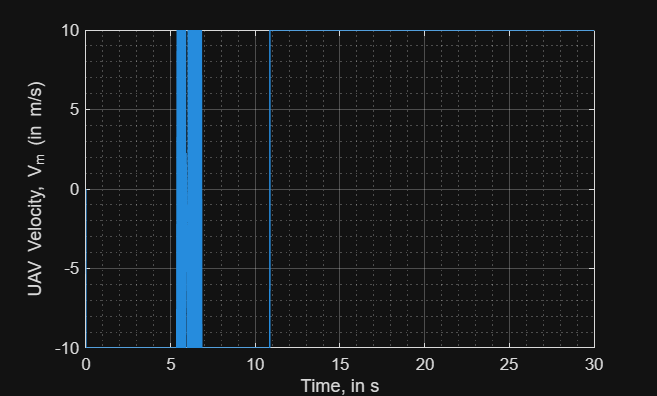


figure;
plot(0:dt:simTime, stateM(:, 3), lineWidth=1.5);
hold on;
grid on;
grid minor;
xlabel("Time, in s");
ylabel("UAV Velocity, V_m (in m/s)");
hold off;

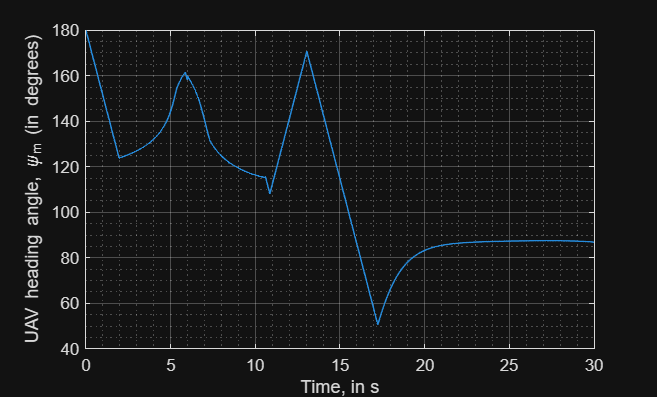


figure;
plot(0:dt:simTime, stateM(:, 4)*180/pi, lineWidth=1.5);
hold on;
grid on;
grid minor;
xlabel("Time, in s");
ylabel("UAV heading angle, \psi_m (in degrees)");
hold off;

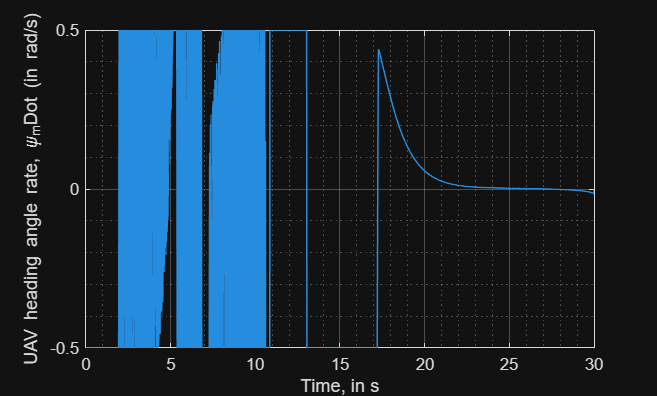


figure;
plot(0:dt:simTime, stateM(:, 5), lineWidth=1.5);
hold on;
grid on;
grid minor;
xlabel("Time, in s");
ylabel("UAV heading angle rate, \psi_mDot (in rad/s)");
hold off;

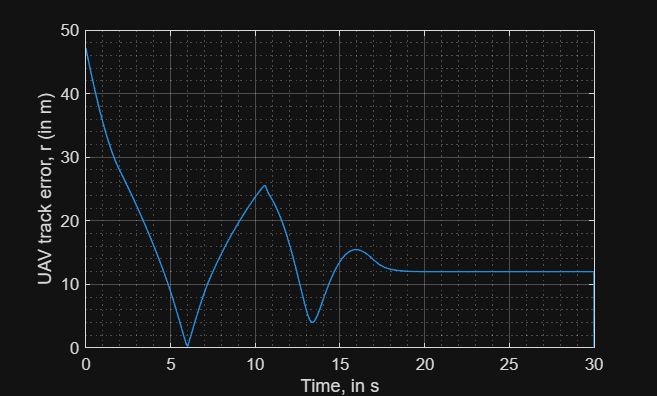


figure;
plot(0:dt:simTime, stateM(:, 7), lineWidth=1.5);
hold on;
grid on;
grid minor;
xlabel("Time, in s");
ylabel("UAV track error, r (in m)");
hold off;